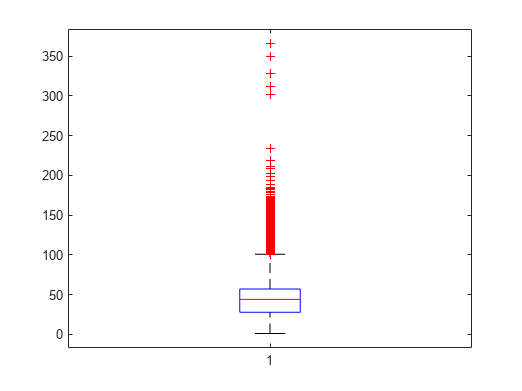

% Load data
load('P2_1.mat'); % Replace 'train_data.mat' with other name
name = 'P2_1';
data = train_data;
boxplot(data.pm2d5)

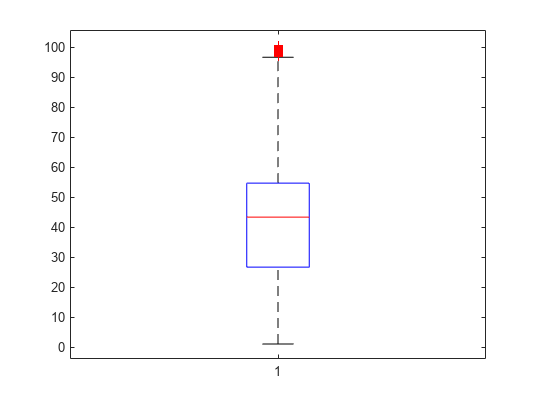

% Assuming the table is named T and the target variable is named 'pm2d5'
% Calculate the IQR for the pm2d5 column
Q1 = quantile(data.pm2d5, 0.25);
Q3 = quantile(data.pm2d5, 0.75);
IQR = Q3 - Q1;

% Define the outlier criteria
lower_bound = Q1 - 1.5 * IQR;
upper_bound = Q3 + 1.5 * IQR;

% Find rows with outliers
outlier_indices = data.pm2d5 < lower_bound | data.pm2d5 > upper_bound;
% pm2d5_zscores = zscore(data.pm2d5);
% z_threshold = 3; % Define the z-score threshold
% outlier_indices = abs(pm2d5_zscores) > z_threshold;

% Remove the outliers
data_clean = data(~outlier_indices, :);
boxplot(data_clean.pm2d5)

% Create a new variable name for the cleaned data
cleaned_var_name = ['cleaned_', name];

% Assign the cleaned data to a variable with the new name
eval([cleaned_var_name ' = data_clean;']);

% Save the cleaned data to a .mat file with the new variable name
save([cleaned_var_name '.mat'], cleaned_var_name);

